clear;
% Plant
T = .1;
P = tf(1, [1 1]);
b = 1-exp(-T);
a = exp(-T);
%P2 = ss(a,b,1,0,T)
%P2d = tf(P2)
% plant equivalent discrete-time model
Pd = c2d(P,T)

Pd =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.




% Controller
Cd = ss(0, 1, -1/T, 1/T, T)

Cd =
 
  A = 
       x1
   x1   0
 
  B = 
       u1
   x1   1
 
  C = 
        x1
   y1  -10
 
  D = 
       u1
   y1  10
 
Sample time: 0.1 seconds
Discrete-time state-space model.




% Forming the Loop
sys_auto = feedback(series(Pd, Cd), 1)

sys_auto =
 
  A = 
             x1        x2
   x1         0    0.3807
   x2       2.5  -0.04679
 
  B = 
         u1
   x1     0
   x2  0.25
 
  C = 
          x1     x2
   y1    -10  3.807
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



sys = ss([a-b/T, -b/T;-1 0],[b/T;1],[1 0], 0, T);
tf(sys)

ans =
 
     0.9516 z - 0.9516
  ------------------------
  z^2 + 0.04679 z - 0.9516
 
Sample time: 0.1 seconds
Discrete-time transfer function.



tf(sys_auto)

ans =
 
     0.9516 z - 0.9516
  ------------------------
  z^2 + 0.04679 z - 0.9516
 
Sample time: 0.1 seconds
Discrete-time transfer function.



syms h real positive
a = exp(-h);
b = 1-exp(-h);
Ad = [a-b/h, -b/h;-1 0];
s = eig(Ad)

$$s = \begin{array}{l} \left(\begin{array}{c} \frac{{\mathrm{e}}^{-h}\,\left(h-{\mathrm{e}}^{h}+\sigma_{1}+1\right)}{2\,h}\\ \frac{{\mathrm{e}}^{-h}\,\left(h-{\mathrm{e}}^{h}-\sigma_{1}+1\right)}{2\,h} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2\,h+{\mathrm{e}}^{2\,h}-2\,{\mathrm{e}}^{h}-6\,h\,{\mathrm{e}}^{h}+h^{2}+4\,h\,{\mathrm{e}}^{2\,h}+1} \end{array}$$

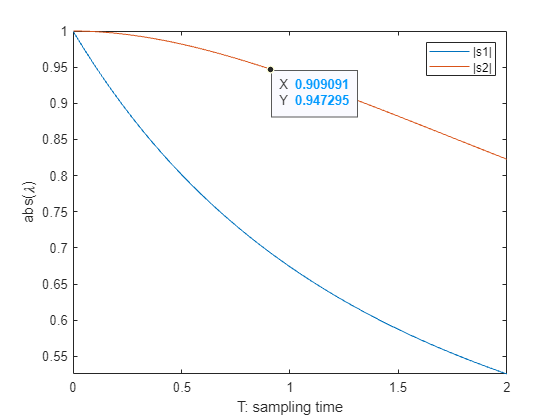

cla;
fplot(abs(s(1)), [0,2], 'DisplayName', '|s1|')
hold on;
fplot(abs(s(2)), [0, 2], 'DisplayName', '|s2|')
xlabel('T: sampling time');
ylabel('abs(\lambda)');

legend;